mandelPoints = fWithoutgMandelbrot(100, 500, 1000)
len = 100000;
[orbitf, orbitg] = matrixOrbit(mandelPoints', len)
fixedPoints = fFixedWithoutgFixed(200, 500, 1000)

theta = 4;
c = (((1 - cos(theta)) / 2) * (cos(theta) + 1i * sin(theta))) + .25

c = -0.2904 - 0.6257i

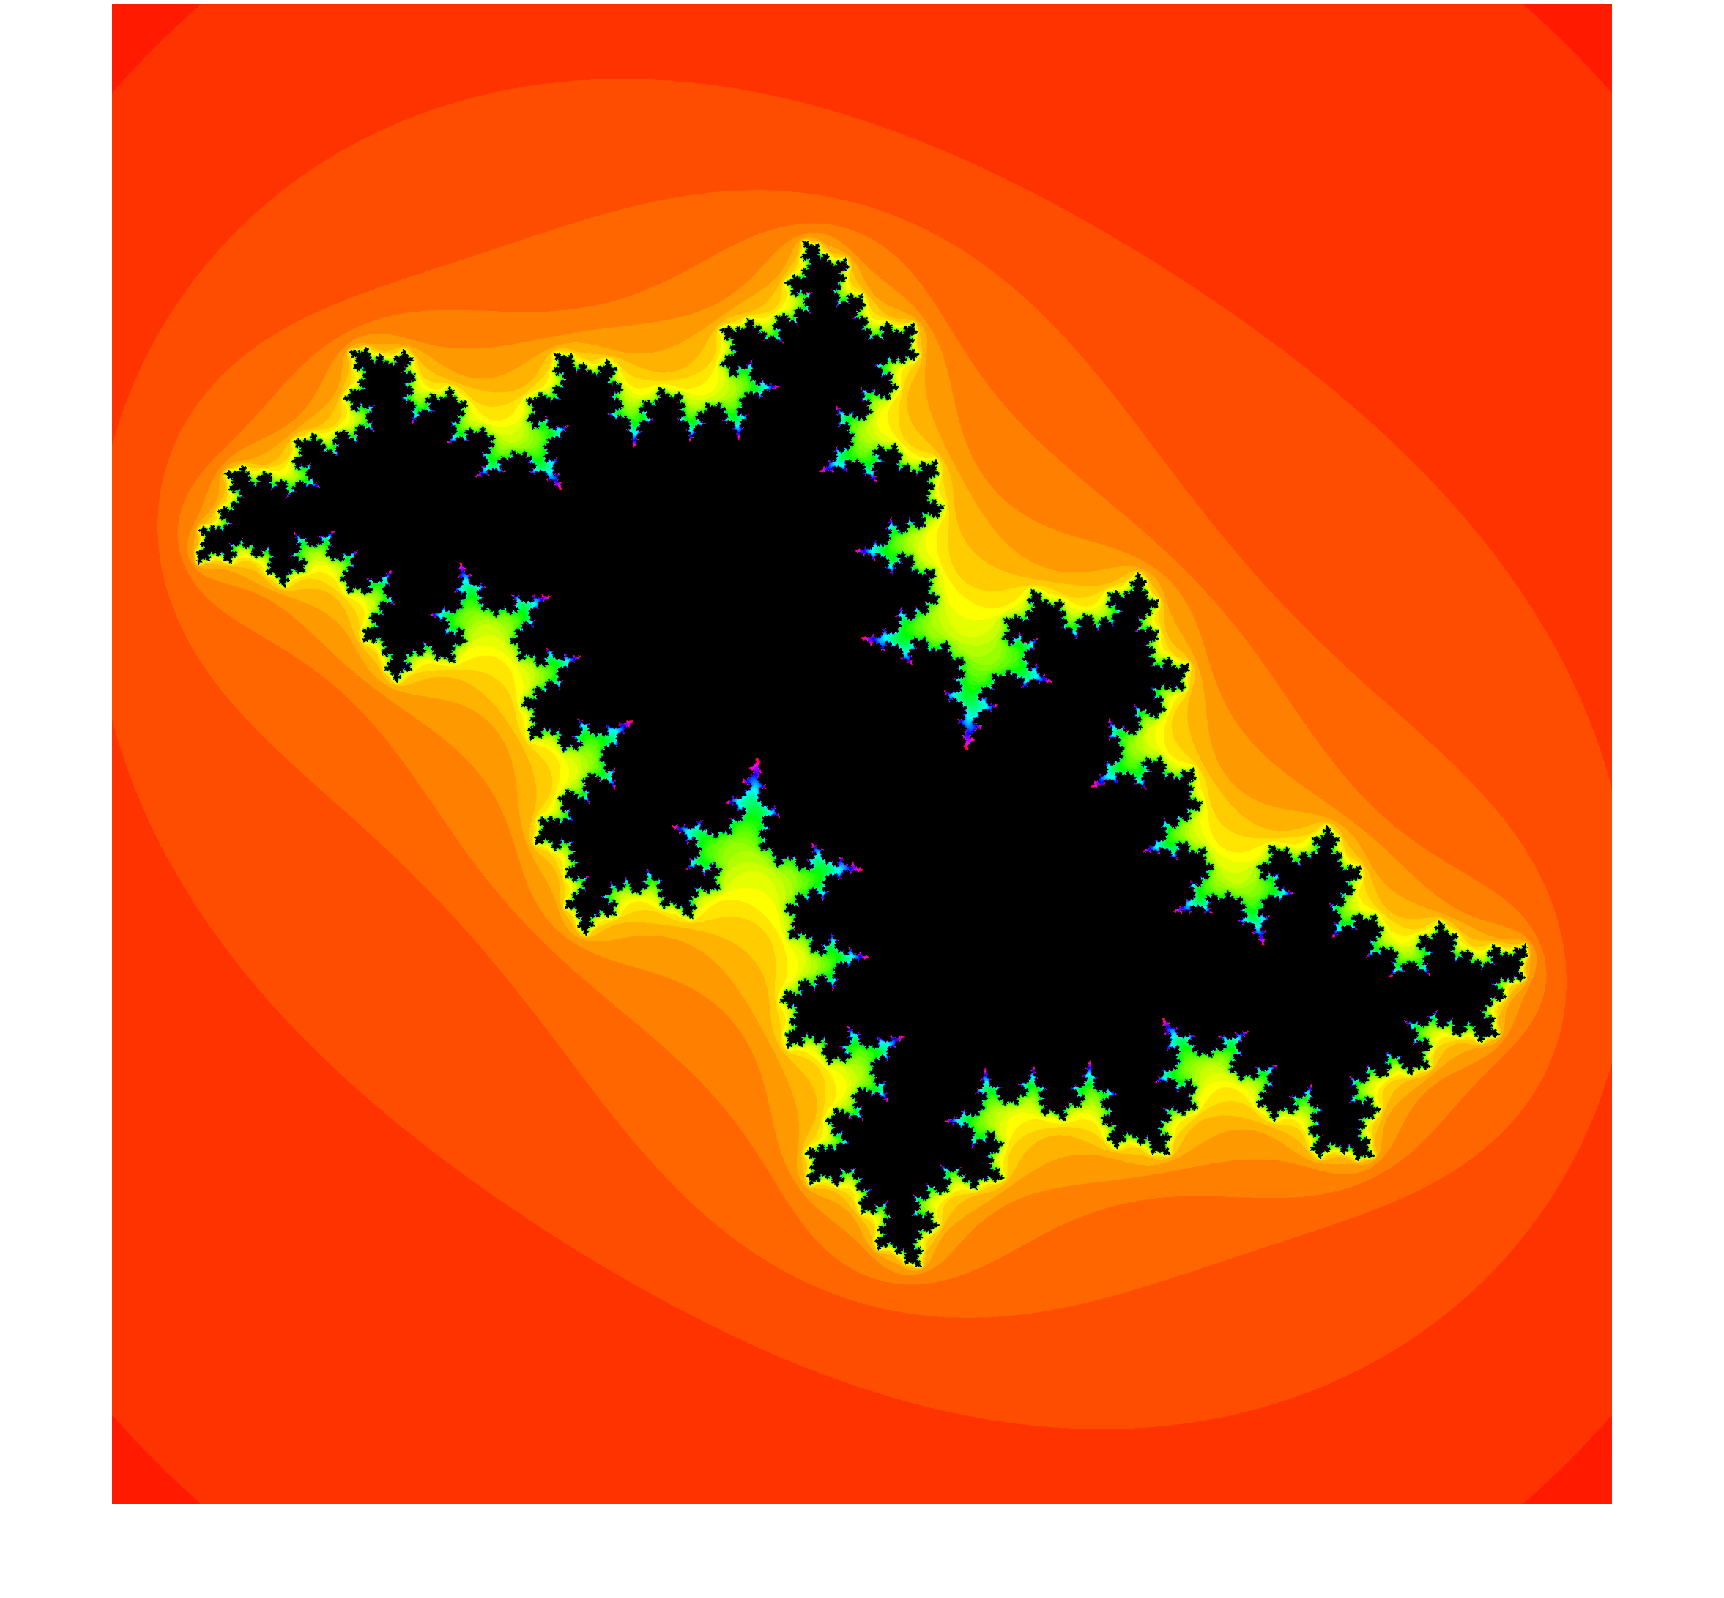

z = -0.3965 - 0.7205i

%c = 0.25 * (cos(theta) + 1i * sin(theta)) - 1 
%c = nan;
z = nan;
len = 10000000;

[orbitf, orbitg] = orbitCalc(len, c, z);


orbit = orbitg;
[m, ind] = max(orbit);
maxNorm = abs(m)

maxNorm = 7.6674e+08

index = ind

index = 9958862

maxNorm = 7.6674e+08

index = 9958862

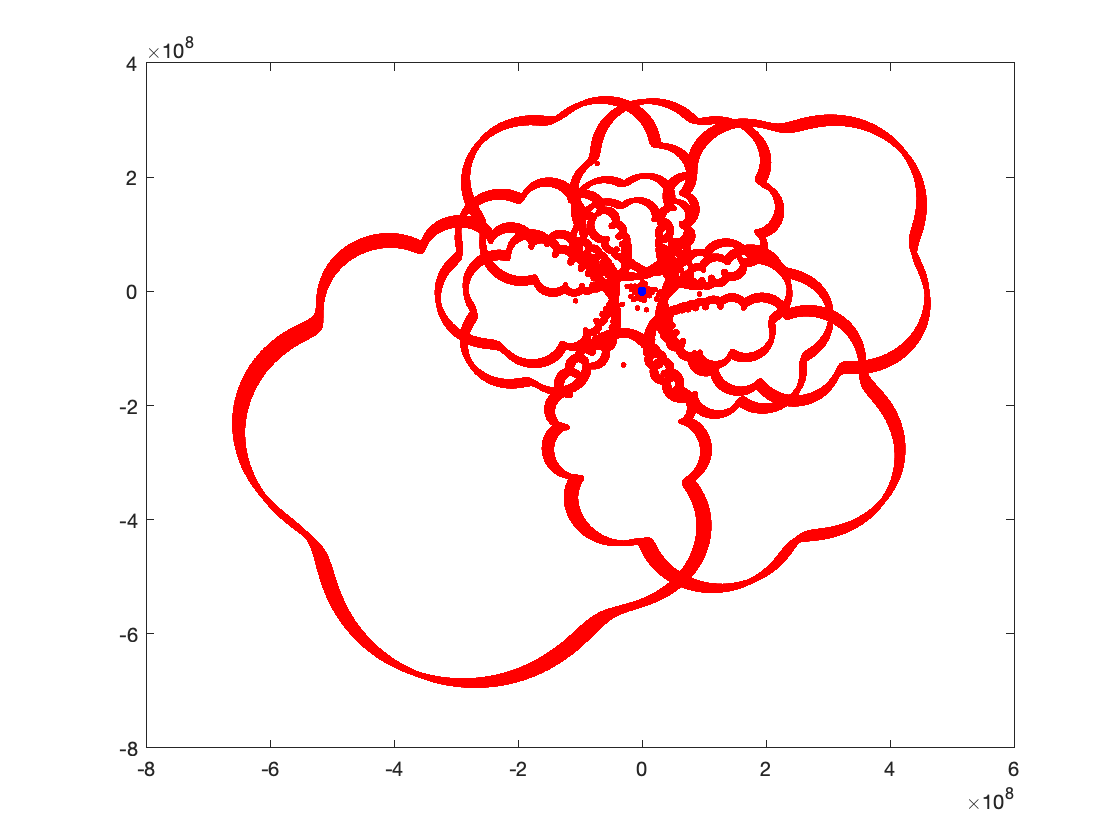

orbit = 	1.0e+08 *

   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i


arrows = nan;

orbit = orbitPlotter(orbit, fixedPoints, arrows)

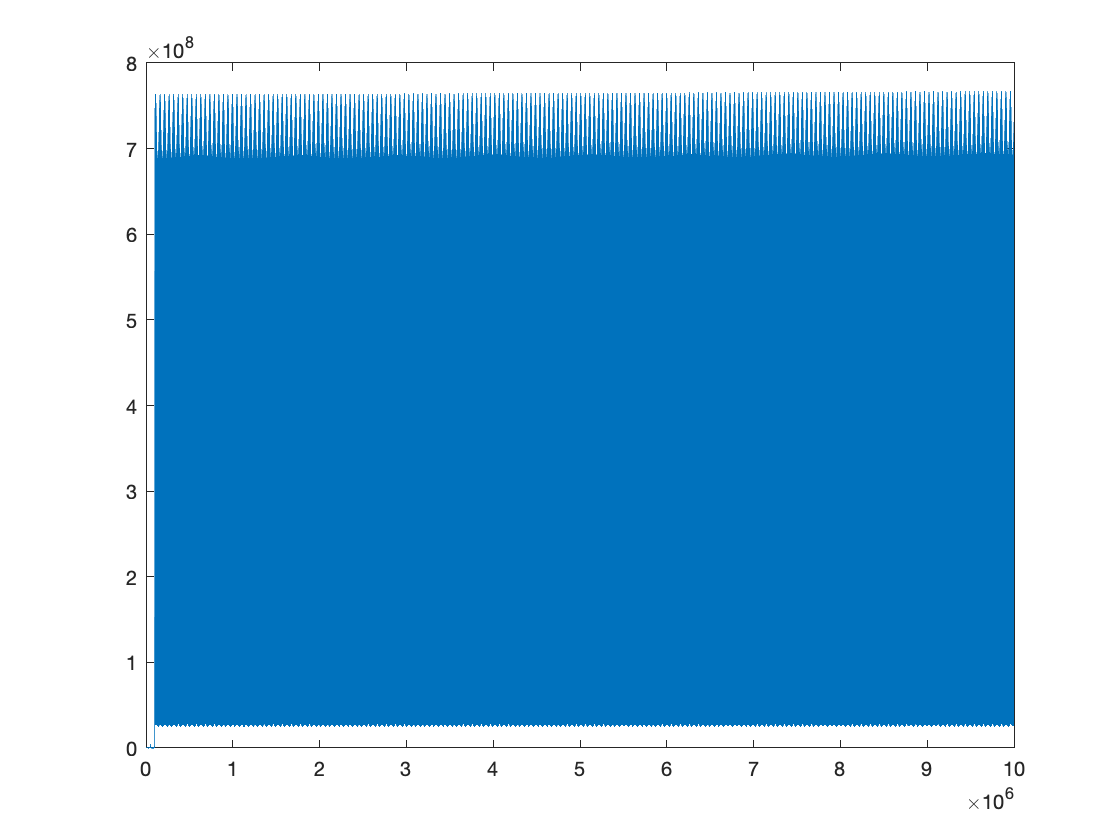


plot(abs(orbit))

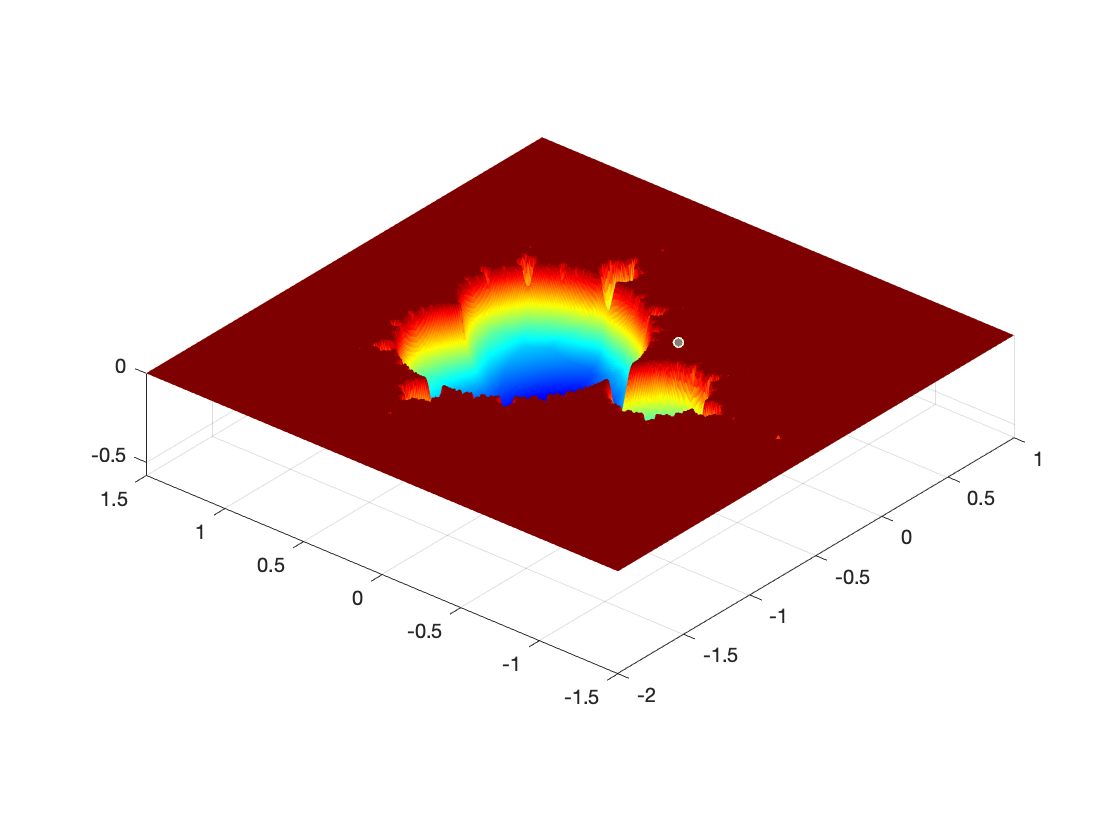

surfaceMandelbrot('g', 500, 30, 1000)

function output = coloredMandelbrotg(max_iter, res, ceiling)
    x = linspace(-2, 1, res);
    y = linspace(-1.5, 1.5, res);
    f = @(z, c) z^2 + c;
    g = @(z1, z2) 2 * z1 * z2;
    hsv_image = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            n = 0;
            z1 = c;
            z2 = 1;
            while abs(z2) < ceiling && n < max_iter
                z2 = g(z1, z2);
                z1 = f(z1, c);
                n = n + 1;
            end
            if n < max_iter
                hsv_image(k, j, 3) = 1;
            else
                n = max_iter;
                hsv_image(k, j, 3) = 0;
            end
            hsv_image(k, j, 1) = n / max_iter;
            hsv_image(k, j, 2) = 1;
        end
    end
    rgb_image = hsv2rgb(hsv_image);
    imshow(rgb_image)
end

function output = fWithoutgMandelbrot(max_iter, res, ceiling)
    x = linspace(-2, 2, res);
    y = linspace(-2, 2, res);
    f = @(z, c) z^2 + c;
    g = @(z1, z2) 2 * z1 * z2 + 1;
    x_axis = [];
    y_axis = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            n1 = 0;
            n2 = 0;
            z1 = c;
            z2 = 1;
            z3 = c;
            while n1 < max_iter && abs(z2) < ceiling
                z2 = g(z1, z2);
                z1 = f(z1, c);
                n1 = n1 + 1;
            end
            while n2 < max_iter && abs(z3) < 2
                z3 = f(z3, c);
                n2 = n2 + 1;
            end
            if n2 == max_iter && n1 < max_iter
                x_axis = [x_axis x(j)];
                y_axis = [y_axis y(k)];
            end
        end
    end
    scatter(x_axis, y_axis, 1, 'filled')
    output = x_axis + y_axis*1i;
end

function output = fFixedWithoutgFixed(max_iter, res, ceiling)
    x = linspace(-2, 2, res);
    y = linspace(-2, 2, res);
    f = @(z, c) z^2 + c;
    g = @(z1, z2) 2 * z1 * z2;
    x_fixed = [];
    y_fixed = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            n1 = 0;
            n2 = 0;
            z1 = c;
            z2 = 1;
            z3 = c;
            while n1 < max_iter && abs(z2) < ceiling
                z2 = g(z1, z2);
                z1 = f(z1, c);
                n1 = n1 + 1;
            end
            while n2 < max_iter && abs(z3) < 2
                z3 = f(z3, c);
                n2 = n2 + 1;
            end
            if n2 == max_iter && n1 < max_iter
                alpha_neg = (1 - sqrt(1 - 4 * c)) / 2;
                alpha_pos = (1 + sqrt(1 - 4 * c)) / 2;
                x_fixed = [x_fixed real(alpha_pos) real(alpha_neg)];
                y_fixed = [y_fixed imag(alpha_pos) imag(alpha_neg)];
            end
        end
    end
    scatter(x_fixed, y_fixed, 5, 'filled')
    output = x_fixed + y_fixed*1i;
end

function [orbitf, orbitg, orbith, orbitm, orbitn] = matrixOrbit(c, l)
    orbitf = [];
    orbitg = [];
    orbith = [];
    orbitm = [];
    orbitn = [];
    zf = c;
    zg = ones(length(c), 1);
    zh = zeros(length(c), 1);
    zm = zeros(length(c), 1);
    zn = zeros(length(c), 1);
    f = @(zf, c) (zf.^2) + c;
    g = @(zf, zg) (2 .* zf .* zg) + 1;
    h = @(zf, zg, zh) (2 .* zf .* zh) + (zg.^2);
    m = @(zf, zg, zh, zm) (2 .* zf .* zm) + (2 .* zg .* zh);
    n = @(zf, zg, zh, zm, zn) (2 .* zf .* zn) + (2 .* zg .* zm) + (zh.^2);
    
    for j = 1:l
        zn = n(zf, zg, zh, zm, zn);
        zm = m(zf, zg, zh, zm);
        zh = h(zf, zg, zh);
        zg = g(zf, zg);
        zf = f(zf, c);
    end
    
    orbitf = abs(zf);
    orbitf = orbitf(~isnan(orbitf));
    orbitf = orbitf(~isinf(orbitf));
    
    orbitg = abs(zg);
    orbitg = orbitg(~isnan(orbitg));
    orbitg = orbitg(~isinf(orbitg));
    
    orbith = abs(zh);
    orbith = orbith(~isnan(orbith));
    orbith = orbith(~isinf(orbith));
    
    orbitm = abs(zm);
    orbitm = orbitm(~isnan(orbitm));
    orbitm = orbitm(~isinf(orbitm));
    
    orbitn = abs(zn);
    orbitn = orbitn(~isnan(orbitn));
    orbitn = orbitn(~isinf(orbitn));
end

function [orbitf, orbitg, orbith, orbitm, orbitn, fixedPoints] = orbitCalc(length, c, z)
    if isnan(c)
        fig = openfig('mandelbrotcolored.fig', 'invisible');
        [x1, y1] = getpts(fig);
        close();
        x1 = 3 * (x1 / 5000) - 2;
        y1 = 3 * (y1 / 5000) - 1.5;
        c = x1 + y1 * 1i
    end
    if isnan(z)
        res = 3000;
        pic = juliaPlotter(c, res, 2, 60);
        imshow(pic);
        savefig('tempJulia.fig');
        fig = openfig('tempJulia.fig', 'invisible');
        [x2, y2] = getpts(fig);
        close();
        x2 = 3 * (x2 / res) - 1.5;
        y2 = 3 * (y2 / res) - 1.5;
        z = x2 + y2 * 1i
    end
    
    orbitf = [c zeros(1, length - 1)];
    orbitg = [c zeros(1, length - 1)];
    orbith = [c zeros(1, length - 1)];
    orbitm = [c zeros(1, length - 1)];
    orbitn = [c zeros(1, length - 1)];
    zf = z^2 + c;
    zg = 2 * zf + 1;
    zh = 0;
    zm = 0;
    zn = 0;
    f = @(zf, c) (zf^2) + c;
    g = @(zf, zg) 2 * zf * zg + 1;
    h = @(zf, zg, zh) (2 * zf * zh) + (zg^2);
    m = @(zf, zg, zh, zm) (2 * zf * zm) + (2 * zg * zh);
    n = @(zf, zg, zh, zm, zn) (2 * zf * zn) + (2 * zg * zm) + (zh^2);
    negFixed = (1 - sqrt(1 - 4 * c)) / 2;
    posFixed = (1 + sqrt(1 - 4 * c)) / 2;
    fixedPoints = [negFixed posFixed];
    
    for j = 1:length
        zn = n(zf, zg, zh, zm, zn);
        zm = m(zf, zg, zh, zm);
        zh = h(zf, zg, zh);
        zg = g(zf, zg);
        zf = f(zf, c);
        orbitn(j) = zn;
        orbitm(j) = zm;
        orbith(j) = zh;
        orbitg(j) = zg;
        orbitf(j) = zf;
    end
end

function output = juliaPlotter(c, res, ceiling, iter)
    x = linspace(-1.5, 1.5, res);
    y = linspace(-1.5, 1.5, res);
    [X, Y] = meshgrid(x,y);
    Z = X + 1i*Y;
    hsv(:, :, 1) = zeros(res);
    hsv(:, :, 2) = zeros(res);
    hsv(:, :, 3) = zeros(res);
    for row=1:res
        for col=1:res
            z = Z(row,col);
            for j = 1:iter
                if abs(z) > ceiling
                    break
                else
                    z = z^2 + c;
                end
            end
            if j < iter
                hsv(row, col, 3) = 1;
            else
                hsv(row, col, 3) = 0;
            end
                hsv(row,col,1) = j/iter;
                hsv(row,col,2) = 1;
        end
    end
    output = hsv2rgb(hsv);
end

function output = orbitPlotter(orbit, fixedPoints, arrows)
    [m, ind] = max(orbit);
    maxNorm = abs(m)
    index = ind
    close all;
    X = real(orbit);
    Y = imag(orbit);
    dX = diff(X);
    dY = diff(Y);
    plot(X, Y, '.', 'color', [1 0 0], 'MarkerSize', 7)
    hold on
    plot(real(fixedPoints(1)), imag(fixedPoints(1)), '.', 'color', [0 0 1], 'MarkerSize', 12)
    if ~isnan(arrows)
        quiver(X(1:end-1),Y(1:end-1), dX, dY, 0)
    end
    %axis(corners)
    hold off
    output = orbit;
end

function output = surfaceMandelbrot(func, res, max_iter, ceiling)
    x = linspace(-2, 1, res);
    y = linspace(-1.5, 1.5, res);
    x_axis = linspace(-2, 1, res);
    y_axis = linspace(-1.5, 1.5, res);
    z_grid = zeros(res);
    zg = 1;
    zh = 0;
    zm = 0;
    zn = 0;
    f = @(zf, c) (zf^2) + c;
    g = @(zf, zg) (2 * zf * zg) + 1;
    h = @(zf, zg, zh) (2 * zf * zh) + (zg^2);
    m = @(zf, zg, zh, zm) (2 * zf * zm) + (2 * zg * zh);
    n = @(zf, zg, zh, zm, zn) (2 * zf * zn) + (2 * zg * zm) + (zh^2);
    
    if func == 'f'
        for j = 1:res
            for k = 1:res
                c = x(j) + y(k)*1i;
                zf = c;
                zg = 1;
                zh = 0;
                zm = 0;
                zn = 0;
                iter = 0;
                norm = 0;
                while iter < max_iter && abs(zf) < ceiling
                    zf = f(zf, c);
                    if norm < abs(zf)
                        norm = abs(zf);
                    end
                    iter = iter + 1;
                end
                if iter == max_iter
                    z_grid(j, k) = -1 / (1 + norm);
                else
                    z_grid(j, k) = 0;
                end
            end
        end
    
    elseif func == 'g'
        for j = 1:res
            for k = 1:res
                c = x(j) + y(k)*1i;
                zf = c;
                zg = 1;
                zh = 0;
                zm = 0;
                zn = 0;
                iter = 0;
                norm = 0;
                while iter < max_iter && abs(zg) < ceiling
                    zg = g(zf, zg);
                    zf = f(zf, c);
                    if norm < abs(zg)
                        norm = abs(zg);
                    end
                    iter = iter + 1;
                end
                if iter == max_iter
                    z_grid(j, k) = -1 / (1 + norm);
                else
                    z_grid(j, k) = 0;
                end
            end
        end
    
    elseif func == 'h'
        for j = 1:res
            for k = 1:res
                c = x(j) + y(k)*1i;
                zf = c;
                zg = 1;
                zh = 0;
                zm = 0;
                zn = 0;
                iter = 0;
                norm = 0;
                while iter < max_iter && abs(zh) < ceiling
                    zh = h(zf, zg, zh);
                    zg = g(zf, zg);
                    zf = f(zf, c);
                    if norm < abs(zh)
                        norm = abs(zh);
                    end
                    iter = iter + 1;
                end
                if iter == max_iter
                    z_grid(j, k) = -1 / (1 + norm);
                else
                    z_grid(j, k) = 0;
                end
            end
        end
    
    elseif func == 'm'
        for j = 1:res
            for k = 1:res
                c = x(j) + y(k)*1i;
                zf = c;
                zg = 1;
                zh = 0;
                zm = 0;
                zn = 0;
                iter = 0;
                norm = 0;
                while iter < max_iter && abs(zm) < ceiling
                    zm = m(zf, zg, zh, zm);
                    zh = h(zf, zg, zh);
                    zg = g(zf, zg);
                    zf = f(zf, c);
                    if norm < abs(zm)
                        norm = abs(zm);
                    end
                    iter = iter + 1;
                end
                if iter == max_iter
                    z_grid(j, k) = -1 / (1 + norm);
                else
                    z_grid(j, k) = 0;
                end
            end
        end
    
    elseif func == 'n'
        for j = 1:res
            for k = 1:res
                c = x(j) + y(k)*1i;
                zf = c;
                zg = 1;
                zh = 0;
                zm = 0;
                zn = 0;
                iter = 0;
                norm = 0;
                while iter < max_iter && abs(zn) < ceiling
                    zn = n(zf, zg, zh, zm, zn);
                    zm = m(zf, zg, zh, zm);
                    zh = h(zf, zg, zh);
                    zg = g(zf, zg);
                    zf = f(zf, c);
                    if norm < abs(zn)
                        norm = abs(zn);
                    end
                    iter = iter + 1;
                end
                if iter == max_iter
                    z_grid(j, k) = -1 / (1 + norm);
                else
                    z_grid(j, k) = 0;
                end
            end
        end
    end
    
    figure
    colormap jet
    surf(x_axis, y_axis, z_grid, 'LineStyle', 'none')
    daspect([2 2 2])
    axis tight
    view(-50,30)
    %camlight left
end